This notebook is created by 

*Asif Newaz*

*Lecturer, EEE, IUT*

*MATLAB version: 2022a*

It provides a historical analysis of the wildfire events occurred in the USA in between 2015 and 2018.

## Data Import

data_18= readtable('StormEvents_2018.csv');
data_17= readtable('StormEvents_2017.csv');
data_16= readtable('StormEvents_2016.csv');
data_15= readtable('StormEvents_2015.csv');
data_14= readtable('StormEvents_2014.csv');

% joining the data
df= vertcat(data_18, data_17, data_16, data_15, data_14);
head(df,10)

ans = 10×23 table
    EpisodeID      Event_ID        State        Year     Month           Event_Type            Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                 Episode_Narrative                                                             

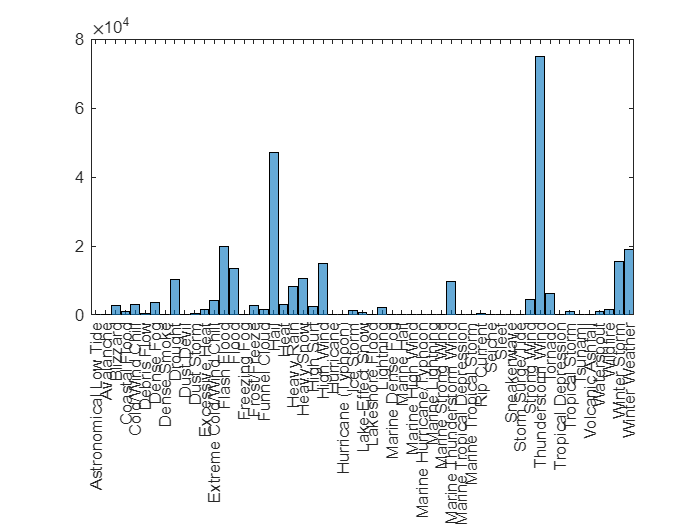

% event count
histogram(df.Event_Type)

Hail and thunder storms are most frequent.

## Wildfire events

wf= df(df.Event_Type == "Wildfire",:);
head(wf,5)

ans = 5×23 table
    EpisodeID      Event_ID      State      Year     Month      Event_Type      Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                      Episode_Narrative<

### By State

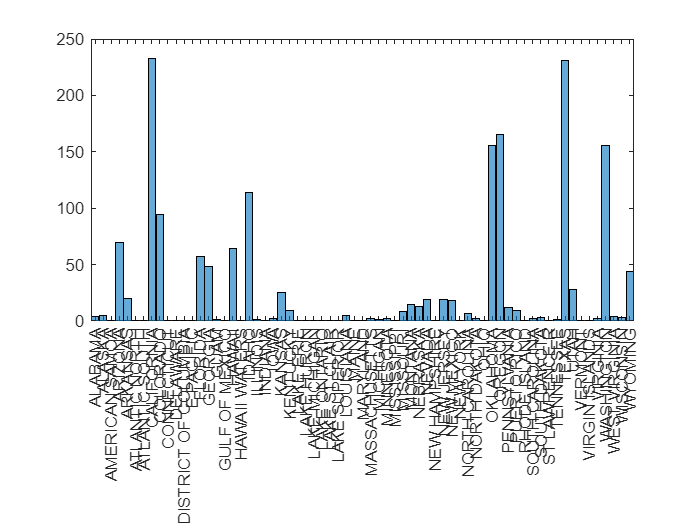

% wildfire events count by state
histogram(wf.State)

California and Texas are mostly affected by wildfires.

### By month

% monthly occurrence
wm=groupcounts(wf, 'Month')

wm = 12×3 table
      Month      GroupCount    Percent
    _________    __________    _______

    April           122        7.2879 
    August          325        19.415 
    December         34        2.0311 
    February        105        6.2724 
    January          69        4.1219 
    July            305         18.22 
    June            126        7.5269 
    March           188        11.231 
    May              81        4.8387 
    November         61         3.644 
    October          88        5.2569 
    September       170        10.155 


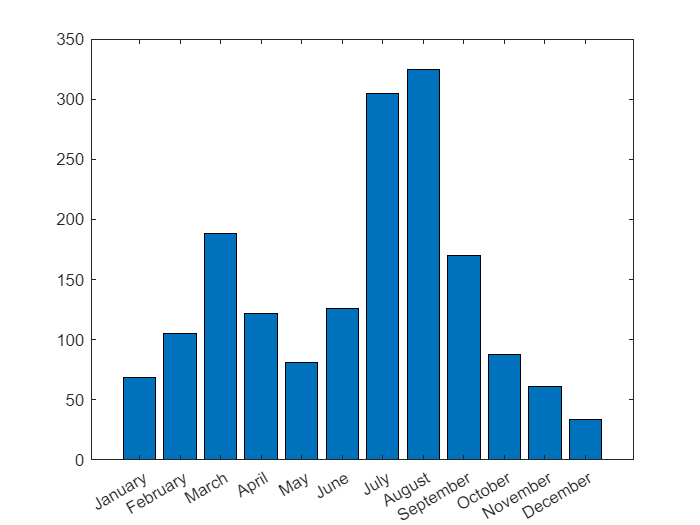

month= {'January','February', 'March','April', 'May', 'June', 'July', 'August', 'September', 'October', 'November', 'December'};
val = [69,105,188,122,81,126,305,325,170,88,61,34];
bar(val)
xticklabels(month)

### By year

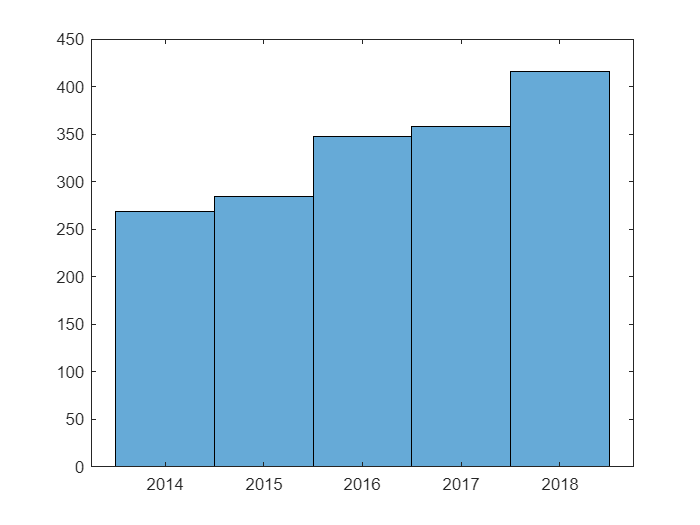

h =   Histogram with properties:

             Data: [1674×1 double]
           Values: [269 284 347 358 416]
          NumBins: 5
         BinEdges: [2.0135e+03 2.0145e+03 2.0155e+03 2.0165e+03 2.0175e+03 2.0185e+03]
         BinWidth: 1
        BinLimits: [2.0135e+03 2.0185e+03]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h= histogram(wf.Year)

## Removing unnecessary columns

wf2 = removevars(wf, {'EpisodeID','Event_ID','Begin_Date_Time','Event_Type','Timezone','End_Date_Time','Begin_Lat','Begin_Lon','End_Lat','End_Lon'});

### Death counts

wf2.death= wf2.Deaths_Direct + wf2.Deaths_Indirect;
wf2.injuries = wf2.Injuries_Direct + wf2.Injuries_Indirect;
wf2.casualties = wf2.death + wf2.injuries;
head(wf2,5)

ans = 5×16 table
     State      Year     Month      Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                      Episode_Narrative                                                                                                                                                                                                                                                                                                                       

sum(wf2.casualties)

ans = 497

sum(wf2.death)

ans = 159

There were in total 159 deaths in the last 5 years. lets see the distribution by year.

dy= groupsummary(wf2,"Year","sum","death")

dy = 5×3 table
    Year    GroupCount    sum_death
    ____    __________    _________

    2014       269             5   
    2015       284            10   
    2016       347             6   
    2017       358            25   
    2018       416           113   


2018 saw a huge number of deaths. What could be the reason?

### Major wildfire events

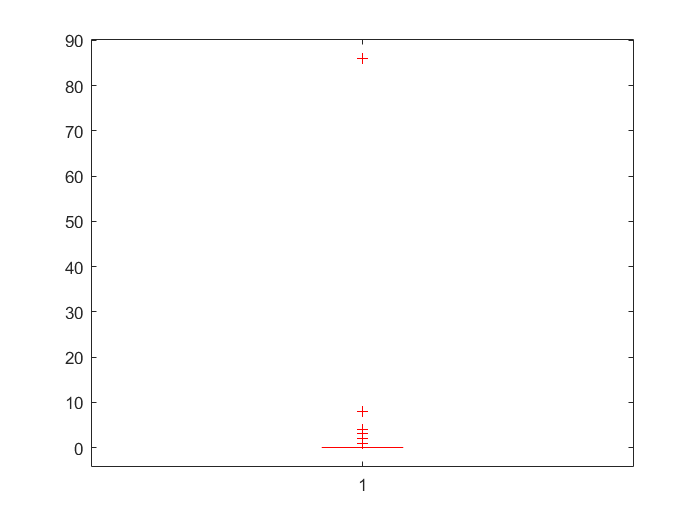

boxplot(wf2.death)

one event caused huge number of deaths.

[val, ind]=maxk(wf2.death,5)

val =     86
     8
     4
     4
     3


ind =          412
         417
         709
        1362
          62


max_death_event= wf2(412,:)

max_death_event = 1×16 table
      State       Year     Month      Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                            Episode_Narrative                                                                                                                                                                                                                                                                                                                                                                                                                                                   

This particular incident in California casued huge casualties and property damage (estimated amount 17B USD). Let's look at the event narrative.

max_death_event.Episode_Narrative

ans = 1×1 cell array
    {'An extended period of dry weather through the summer and fall with above normal temperatures coupled with a gusty north to northeast wind event created a situation for extremely rapid fire growth. A large wildfire developed, the deadliest and most destructive in history for California.'}


% the most destructive wildfire in the history of California
string(max_death_event.Event_Narrative)

ans = "The Camp Fire began on the morning of November 8, 2018, by Camp Creek Road, near Pulga in Butte County. The fire was not fully contained until November 25. This fire was the most destructive wildfire in California history, destroying much of the city of Paradise, the community of Concow, and damaging the towns of Pulga and Magalia. There were 18,804 structures destroyed, 13,696 of them single homes, along with 514 commercial structures and 3,718 outbuildings and 153,336 acres burned. There were a total of 86 deaths from the fire, with 12 civilians and 5 firefighters injured. There were 3 people missing as of 1/24/2019, when Butte County Sheriff closed their missing persons call center for the Camp Fire. Damage costs to insured buildings has been estimated to be at least $10 billion. |Conditions which lead to this fire included several recent years with drought conditions, late spring rainfall bringing additional growth of grass for fuel, dry weather for seven months prior to the

Details can be found here - https://en.wikipedia.org/wiki/2018_California_wildfires

## Property damage by wildfires

wf2.Property_Cost= fillmissing(wf2.Property_Cost, "constant",0);
wf2.Crop_Cost = fillmissing(wf2.Crop_Cost, 'constant', 0);
head(wf2,6)

ans = 6×16 table
     State      Year     Month      Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                 Episode_Narrative                                                                                                                                                            

wf2.total_cost= wf2.Property_Cost + wf2.Crop_Cost;

sum(wf2.total_cost)/1e9

ans = 19.5316

Thats 19.5 Billion USD

% damage by state
ts= groupsummary(wf2,"State","sum","total_cost");

sortrows(ts,"sum_total_cost")

ans = 41×3 table
        State         GroupCount    sum_total_cost
    ______________    __________    ______________

    ALABAMA                4                0     
    GUAM                   1                0     
    ILLINOIS               1                0     
    KENTUCKY               9                0     
    MASSACHUSETTS          2                0     
    SOUTH CAROLINA         2                0     
    SOUTH DAKOTA           3                0     
    VIRGINIA               2                0     
    PUERTO RICO            9             1000     
    PENNSYLVANIA          12             3500     
    IOWA                   2             5000     
    MONTANA               15            10000     
    MICHIGAN               1            20000     
    HAWAII                64            50000     
    WEST VIRGINIA          4            50000     
    TENNESSEE

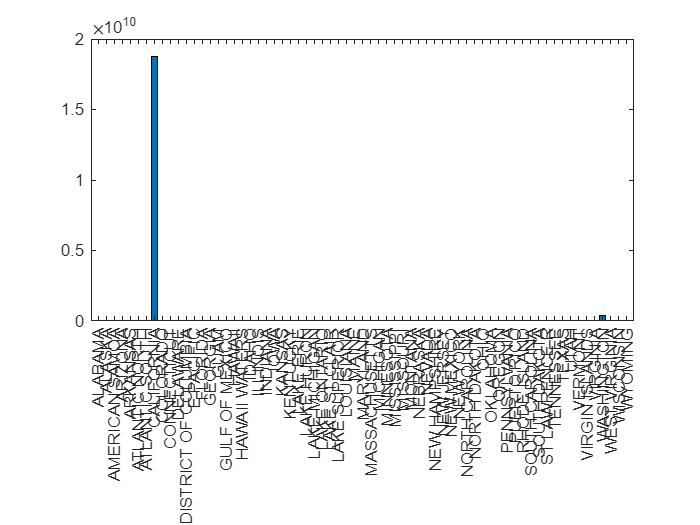

bar(ts.State,ts.sum_total_cost,'DisplayName','ts.sum_total_cost')

California singelhandedly suffered the most damage to property than all other states combined. What about Texas?

### Texas events

texas = wf2(wf2.State=="TEXAS",:);
head(texas, 10)

ans = 10×17 table
    State    Year    Month    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         Episode_Narrative                         

The cost to property information is not available for most cases in Texas. Lets see what the event narratives are.

groupcounts(texas,"Year")

ans = 5×3 table
    Year    GroupCount    Percent
    ____    __________    _______

    2014        27        11.688 
    2015        40        17.316 
    2016        55         23.81 
    2017        34        14.719 
    2018        75        32.468 


2018 saw an increase of events (almost double than previous year).

texas_14= texas(texas.Year== 2014, :)

texas_14 = 27×17 table
    State    Year     Month      Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              Episode_Narrative                                                                            

texas_14(end,"Episode_Narrative")

ans = table
                                                                                                                                                                                                                                                                                                     Episode_Narrative                                                                                                                                                                                                                                                                                                  
    ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________